# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long

path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';
country_SA = StatisticsAnalysis('TablePath', path_country);
country = country_SA.Table;
daily_SA = StatisticsAnalysis('TablePath', path_daily, ...
    'ImportOptions', {'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}} ...
    );
daily = daily_SA.Table;
daily_location = unique(daily{:,'location'});
country_location = unique(country{:,'location'});
country_daily = country(ismember(country_location, daily_location), :);
country_daily(any(ismissing(country_daily)')',:) = []

country_daily = 20×13 table
        location            continent        population    population_density    median_age    aged_65_older    aged_70_older    gdp_per_capita    male_smokers    female_smokers    cardiovasc_death_rate    hospital_beds_per_thousand    life_expectancy
    ________________    _________________    __________    __________________    __________    _____________    _____________    ______________    ____________    ______________    _____________________    __________________________    _______________

    {'Australia'   }    {

## 第一部分：数据导入与可视化（StatisticsAnalysis类）

利用StatisticsAnalysis对象，一步完成（1）导入参数的检测、修改；（2）数据的导入；（3）表格的检索；（4）一般统计指标的计算.

Example: 法国2020年至2022年4月的每日新增阳性与每日新增疫苗接种量.

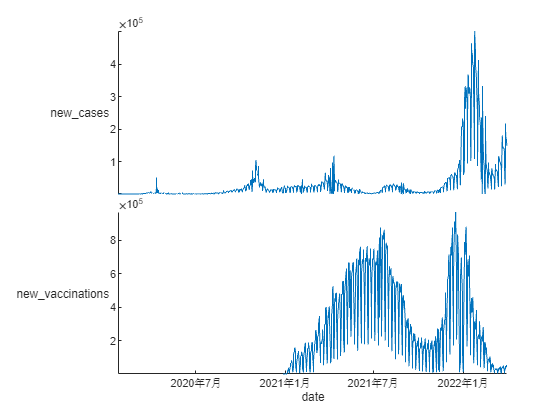

SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}, ...
        'SelectedVariableNames', {'date', 'new_cases', 'new_vaccinations'} ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France', ... Country
        'date', arange(["2020-01-01", "2022-04-01"], 'closed') ... Time Range
        }, ...
    'TagsGenerateOptions', { ...
        'CustomTagName', {'increment', [0 1 1], 'continuous', [0 1 1]}, ...
        'CustomTagFunction', { ...
            'increment', 'SummationOfIncrements', @(x,y)tsnansum(x{:,:}) ...
            } ...
        }...
    );
daily = SA.TimeTable;
% figure(1); plot(daily, 'new_cases'); datetick x;
figure(1); stackedplot(daily);

daily.Properties

ans =   TimetableProperties with properties:

               Description: ''
                  UserData: []
            DimensionNames: {'date'  'Variables'}
             VariableNames: {'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowTimes: [799×1 datetime]
                 StartTime: 2020-01-24
                SampleRate: NaN
                  TimeStep: 1d

   Custom Properties (access using t.Properties.CustomProperties.<name>):
     detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [16×3 table]
                      Size: [799 3]
                  TagNames: {{2×1 cell}  {2×1 cell}}
               UniqueCount: {[748]  [460]}
                ValueClass: {'double'  'double'}
              MissingCount: {[10]  [339]}
              MissingRatio: {[0.01

## 第二部分：缺失值处理（tableMissingValuesHelper函数）

利用tableMissingValuesHelper函数，补全缺失值. 例如，在上面的表格daily中，两列增量都各自有所缺少.

Example: 对上一部分导入的数据进行缺失值处理.

% 先检测缺失值的位置，确定其特征，再选用对应的补全方法
[~, missingList] = tableMissingValuesHelper(daily)

missingList = struct with fields:
                 Map: [799×2 logical]
           new_cases: {1×9 cell}
    new_vaccinations: {[1 339]}


% 上面的数据说明，new_cases缺失的数据较分散，而new_vaccinations缺失的数据只分布在起始的一段时间
data2 = table2timetable(SA.FullVarTable(:,{'date', 'new_cases', 'total_cases', 'new_vaccinations', 'total_vaccinations'}));
data2 = tableMissingValuesHelper(data2, 'VariableNames', {'new_cases', 'total_cases'}, 'Style', 'Increment-Addition', 'InterpolationStyle', 'LinearRound');

data2 = tableMissingValuesHelper(data2, 'VariableNames', {'new_vaccinations', 'total_vaccinations'}, 'Style', 'Increment-Addition', 'InterpolationStyle', 'LinearRound', 'ConstantValues', 0);

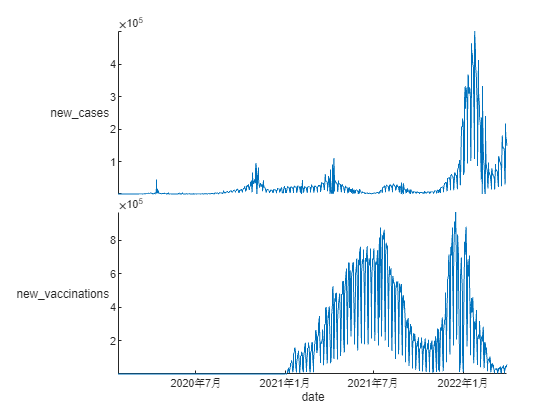

tp = data2(:,{'total_cases'});
tp = renamevars(tp, 'total_cases', 'total_cases_1');
figure(1); stackedplot(data2(:,{'new_cases', 'new_vaccinations'})); % 下面是缺失值处理后的数据作图

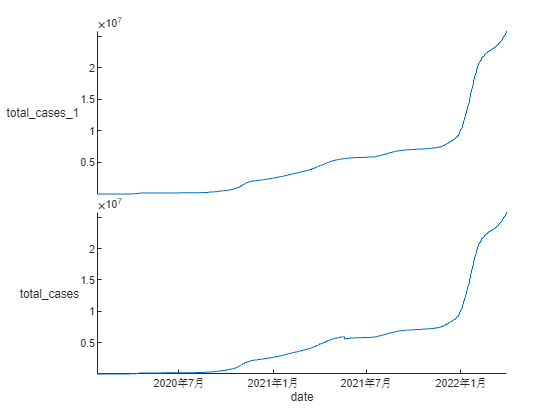

figure(2); stackedplot([tp, SA.FullVarTable(:,{'total_cases'})]);

% 上图是tableMissingValuesHelper修正后的总量，下图是修正前的总量
% 下图中的断层是由于官方数据更正而产生的，这里解决的方法是修正这一行前的所有数据

## 第三部分：一般的统计分析

### Example 1: 对daily表格各列进行统计分析

SA.Table = SA.FullVarTable;
SA.TagsGenerate('TagContinuity',true(1,size(SA.Table,2))).TimeTable.Properties

ans =   TimetableProperties with properties:

               Description: ''
                  UserData: []
            DimensionNames: {'date'  'Variables'}
             VariableNames: {1×12 cell}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowTimes: [799×1 datetime]
                 StartTime: 2020-01-24
                SampleRate: NaN
                  TimeStep: 1d

   Custom Properties (access using t.Properties.CustomProperties.<name>):
     detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [15×13 table]
                      Size: [799 13]
                  TagNames: {1×12 cell}
               UniqueCount: {1×12 cell}
                ValueClass: {1×12 cell}
              MissingCount: {[0]  [0]  [10]  [0]  [110]  [110]  [116]  [339]  [338]  [54]  [54]  [0]}
              Missi

### Example 2: 法国2020年至2022年4月ICU患者占全体住院患者的比例变化趋势图

preRatio = SA.Update('ImportOptions', {'SelectedVariableNames', {'date', 'hosp_patients', 'icu_patients'}}).TimeTable;
% 缺失值处理
[~, missingList] = tableMissingValuesHelper(preRatio)

missingList = struct with fields:
              Map: [799×2 logical]
    hosp_patients: {[1 54]}
     icu_patients: {[1 54]}


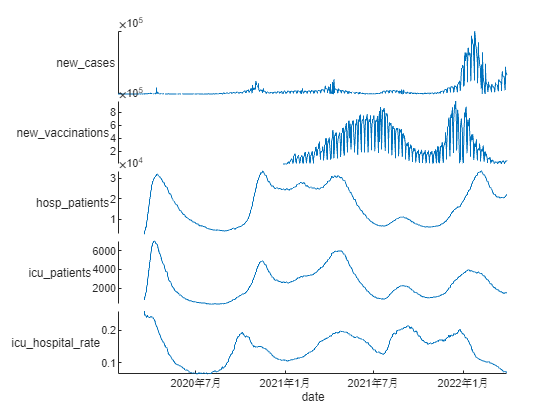

% preRatio = tableMissingValuesHelper(preRatio, 'VariableNames', {'hosp_patients', 'icu_patients'}, 'Style', 'Constant', 'ConstantValues', 0);
Ratio = preRatio(:,2); Ratio = renamevars(Ratio, 'icu_patients', 'icu_hospital_rate');
for idx = 1: size(preRatio, 1)
    Ratio{idx,1} = Ratio{idx,1}./preRatio{idx,1};
end
figure(3); stackedplot([daily,preRatio,Ratio]);

### Example 3: 不同国家的阳性率变化趋势

阳性率(positive rate)是在特定国家/地区的核酸检测中有多少份额确诊。当一个国家的阳性测试率较低时，说明这些国家为防止疫情大规模爆发做出了很多努力；红色表示核酸检测阳性率高，这表明感染的真实数量可能远远高于确诊病例数。

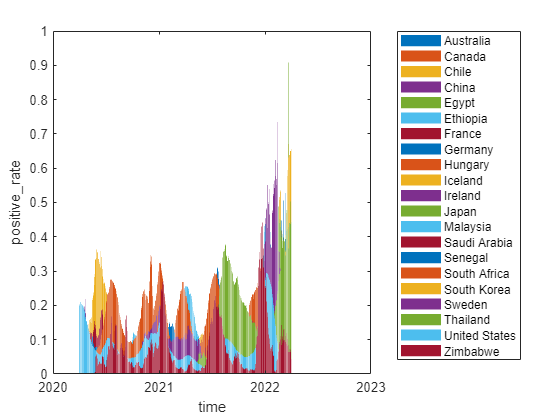

Country = unique(SA.WholeTable{:,'location'}');
SA = SA.Update('ImportOptions', {'SelectedVariableNames', {'date', 'positive_rate'}});
SA = SA.Update('SelectTableOptions', {'date', arange(["2020-04-01", "2022-04-01"], 'closed')});
HighestRate = zeros(1,21);
for idx = 1: length(Country)
    country_name = Country{idx};
    tpPosRate = SA.Update('SelectTableOptions', {'location', country_name}).TimeTable;
    tpPosRate = renamevars(tpPosRate, 'positive_rate', country_name);
    if idx == 1, posRate = tpPosRate;
    else, posRate = [posRate, tpPosRate];
    end
    HighestRate(idx) = tsnanmax(tpPosRate{:,1});
    figure(4); bar(tpPosRate.date, tpPosRate.(country_name)); datetick x; hold on
end
hold off; legend(Country{:}, 'Location', 'NorthEastOutside');
xlabel('time'); ylabel('positive\_rate');

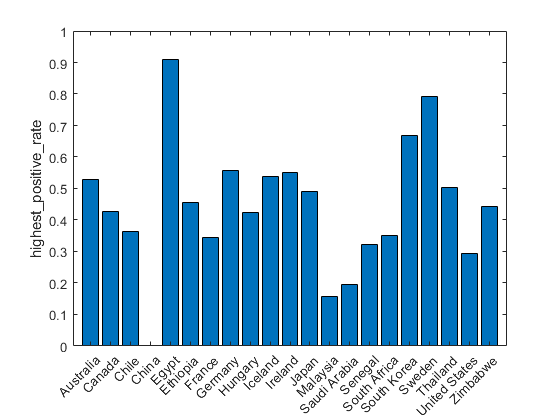

figure(5); bar(categorical(Country), HighestRate); ylabel('highest\_positive\_rate');% 历时最高阳性率

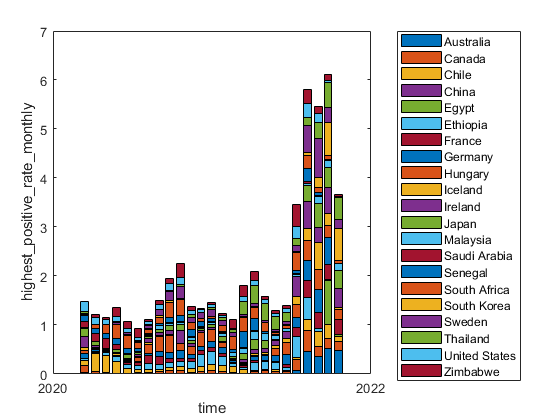

% retime函数可以将日期整合成组，并按照给定方式统计
posRateMonthly = retime(posRate, "monthly", "max");
figure(6); bar(posRateMonthly.date, posRateMonthly{1:end,1:end}, 'stacked'); datetick x;
legend(Country{:}, 'Location', 'NorthEastOutside');
xlabel('time'); ylabel('highest\_positive\_rate\_monthly');

## 第四部分：聚类分析

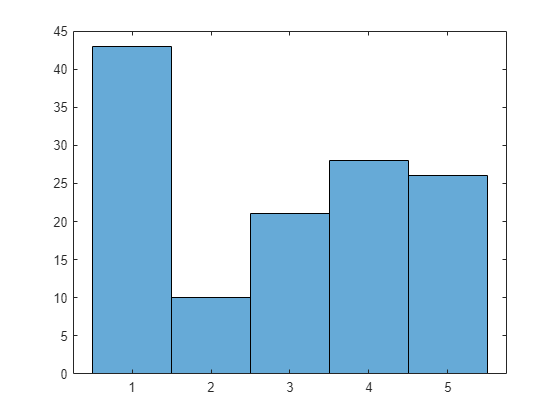

%
record_countries = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'SelectedVariableNames', {'location'} ...
        }...
    ).Table;
record_countries = unique(table2array(record_countries));

path = './data/COVID19/country.csv';
data = StatisticsAnalysis( ...
    'TablePath', path...
    ).Table;
countries = StatisticsAnalysis( ...
    'TablePath', path, ...
    'ImportOptions', { ...
        'SelectedVariableNames', {'location'}...
        }...
    ).Table;

for col = 1:13
    row = ismissing(data(:,col));
    data(row,:) = [];
    countries(row,:) = [];
end

data = table2array(data(:,3:end));
countries = table2array(countries);

% PCA, picking the first five characters 
coeff = pca(data);

char = data*coeff;
char_cut = char(:,5);
num_types = 5;
idx = kmeans(char_cut,num_types);
histogram(idx);

country_type = cell(num_types,1);
for ii = 1:size(idx,1)
    type = idx(ii,1);
    if ismember(countries(ii,1),record_countries)
        country_type{type,1} = [country_type{type,1}, countries(ii,1)];
    end
end
for idx = 1: length(country_type)
    country_type{idx}
end

ans = 1×9 cell array
  Columns 1 through 5

    {'Australia'}    {'Canada'}    {'Egypt'}    {'Iceland'}    {'Ireland'}

  Columns 6 through 9

    {'Malaysia'}    {'South Africa'}    {'United States'}    {'Zimbabwe'}


ans = 1×1 cell array
    {'Chile'}


ans = 1×2 cell array
    {'Ethiopia'}    {'Saudi Arabia'}


ans = 1×3 cell array
    {'China'}    {'Sweden'}    {'Thailand'}


ans = 1×5 cell array
    {'France'}    {'Germany'}    {'Hungary'}    {'Japan'}    {'South Korea'}


% SIR
% myfitVirusCV19(@getDataFrance)

## 第五部分：分析预测

[XSeq_train, YSeq_train] = Data_Preparation({'China','France','United States'},true);

[XSeq_test, YSeq_test] = Data_Preparation({'Australia'},true);

Training:

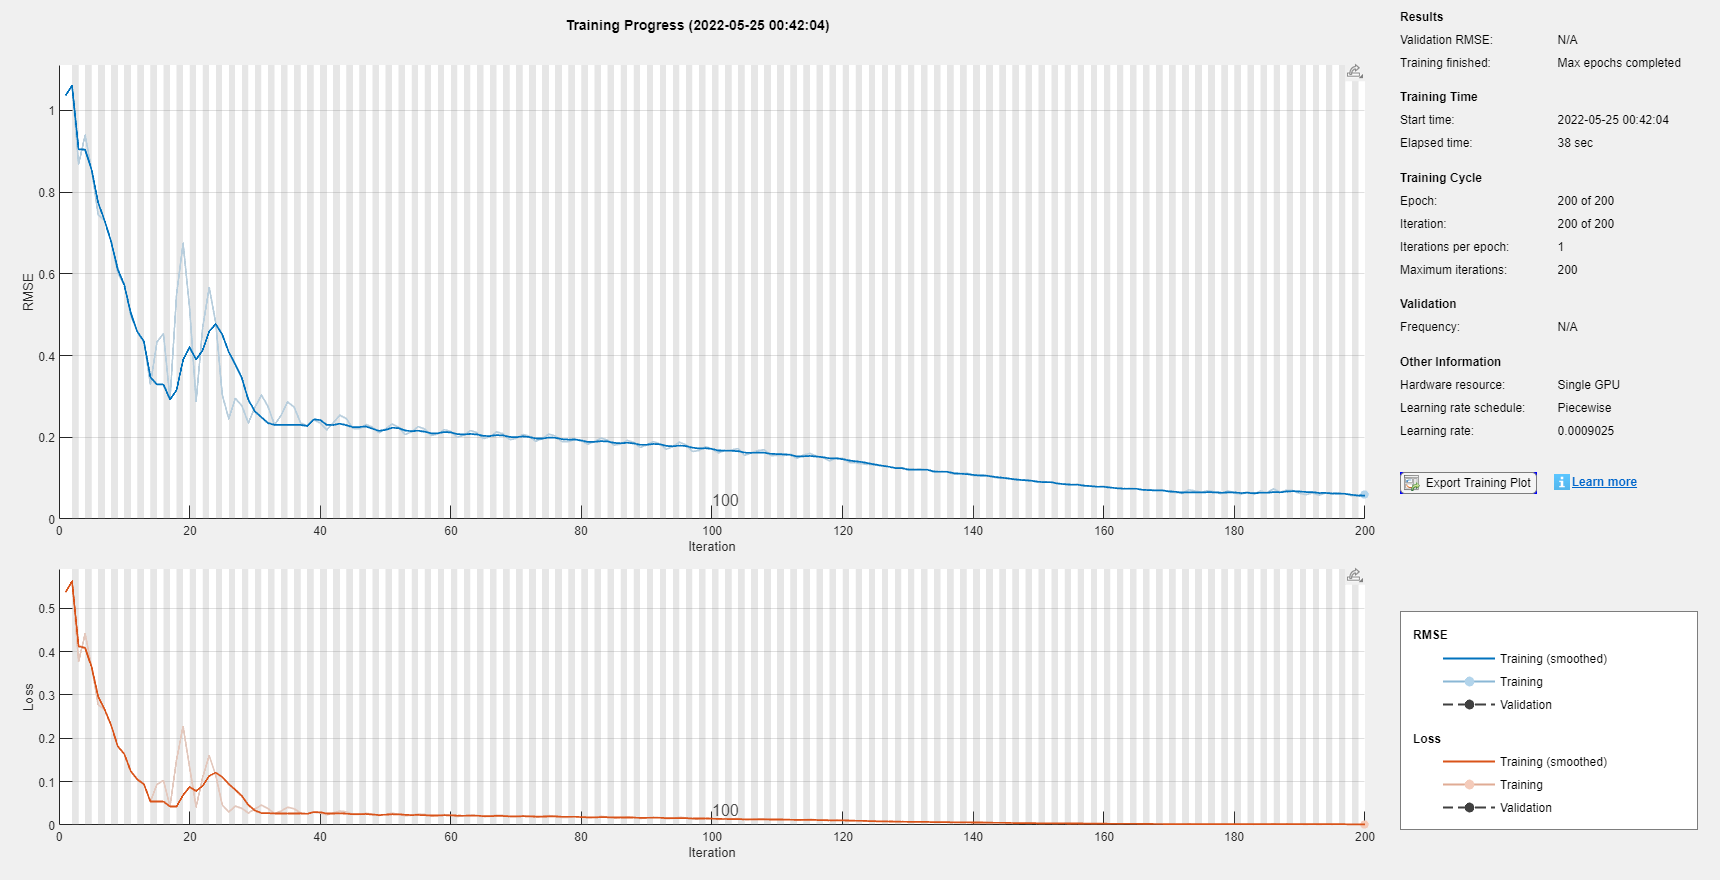

net = PredictNet(XSeq_train,YSeq_train);

Testing:

net = resetState(net);
net = predictAndUpdateState(net,XSeq_train);
numTimeStepsTest = size(XSeq_test,2);
YPred = zeros(1,numTimeStepsTest);
for i = 1:numTimeStepsTest
    [net,YPred(1,i)] = predictAndUpdateState(net,XSeq_test(:,i),'ExecutionEnvironment','gpu');
end

rmse = norm(YPred-YSeq_test)/norm(YSeq_test);
disp(rmse)

   0.391465676878985



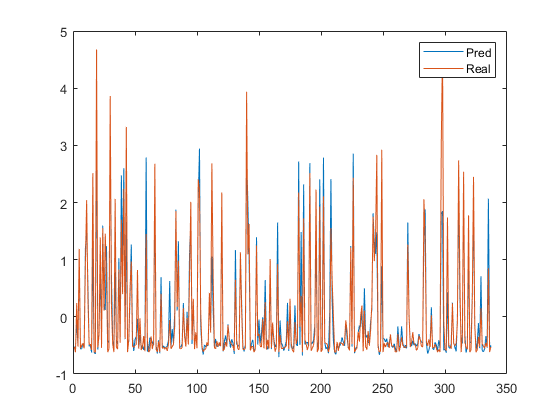


plot(YPred);
hold on;
plot(YSeq_test);
legend('Pred','Real')

% SEIR
% myfitVirusCV19(@getDataTest)